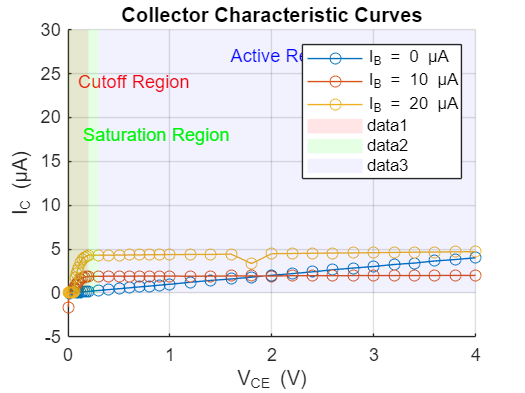

%% ECE370 Lab 5 Analysis

% Clear Workspace and Close Figures
clear; close all; clc;

%% 1. Data Import and Preparation
% Read Data from Excel File (Adjust the sheet name and range as needed)
[data, txt, raw] = xlsread('ECE370-Lab 5.xlsx', 'Sheet1');

% Extract data for each dataset (Adjust column indices based on your file)
Vbe1 = data(:, 1);    % Vbe for Ib = 0 μA
Vcc1 = data(:, 2);    % Vcc for Ib = 0 μA
Vce1 = data(:, 3);    % Vce for Ib = 0 μA
Ic1 = data(:, 4);     % Ic for Ib = 0 μA

Vbe2 = data(:, 5);    % Vbe for Ib = 10 μA
Vcc2 = data(:, 6);    % Vcc for Ib = 10 μA
Vce2 = data(:, 7);    % Vce for Ib = 10 μA
Ic2 = data(:, 8);     % Ic for Ib = 10 μA

Vbe3 = data(:, 9);    % Vbe for Ib = 20 μA
Vcc3 = data(:, 10);   % Vcc for Ib = 20 μA
Vce3 = data(:, 11);   % Vce for Ib = 20 μA
Ic3 = data(:, 12);    % Ic for Ib = 20 μA

Vbe4 = data(:, 13);   % Vbe for Ib = 30 μA
Vcc4 = data(:, 14);   % Vcc for Ib = 30 μA
Vce4 = data(:, 15);   % Vce for Ib = 30 μA
Ic4 = data(:, 16);    % Ic for Ib = 30 μA

% Assign Ib values (in μA)
Ib1 = 0;    % Dataset 1
Ib2 = 10;   % Dataset 2
Ib3 = 20;   % Dataset 3
Ib4 = 30;   % Dataset 4

% Combine data
Vce = [Vce1; Vce2; Vce3; Vce4];
Ic = [Ic1; Ic2; Ic3; Ic4];
Ib = [Ib1 * ones(size(Vce1)); Ib2 * ones(size(Vce2)); Ib3 * ones(size(Vce3)); Ib4 * ones(size(Vce4))];

% Convert currents to Amperes
Ib = Ib * 1e-6;   % Convert Ib from μA to A
Ic = Ic * 1e-6;   % Convert Ic from μA to A

% Define Vcc as the maximum supply voltage
Vcc = max([Vcc1; Vcc2; Vcc3; Vcc4]);

% Ensure Vce and Ic are column vectors
Vce = Vce(:);
Ic = Ic(:);
Ib = Ib(:);

%% 2. Plot VCE against IC for All IB
figure;
hold on;
Ib_values = unique(Ib) * 1e6;  % Convert to μA for labeling
colors = lines(length(Ib_values));  % Distinct colors for each Ib

for i = 1:length(Ib_values)
    idx = Ib == Ib_values(i) * 1e-6;  % Convert back to A for indexing
    plot(Vce(idx), Ic(idx) * 1e6, 'o-', 'Color', colors(i, :), 'DisplayName', ['I_B = ' num2str(Ib_values(i)) ' μA']);
end
xlabel('V_{CE} (V)');
ylabel('I_C (μA)');
title('Collector Characteristic Curves');
legend('show');
grid on;
hold off;

%% 3. Label the Cutoff, Active, and Saturation Regions
figure(1);
hold on;

% Define maximum Ic for scaling
Ic_max = max(Ic) * 1e6;  % Convert to μA

% Regions are approximate; adjust as needed
x_cutoff = [0 0.2];
y_cutoff = [0 Ic_max];
patch([x_cutoff fliplr(x_cutoff)], [y_cutoff(1), y_cutoff(1), y_cutoff(2), y_cutoff(2)], 'red', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
text(0.1, Ic_max * 0.8, 'Cutoff Region', 'Color', 'red');

x_saturation = [0 0.3];
y_saturation = [0 Ic_max];
patch([x_saturation fliplr(x_saturation)], [y_saturation(1), y_saturation(1), y_saturation(2), y_saturation(2)], 'green', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
text(0.15, Ic_max * 0.6, 'Saturation Region', 'Color', 'green');

x_active = [0.3 max(Vce)];
y_active = [0 Ic_max];
patch([x_active fliplr(x_active)], [y_active(1), y_active(1), y_active(2), y_active(2)], 'blue', 'FaceAlpha', 0.05, 'EdgeColor', 'none');
text(mean(x_active), Ic_max * 0.9, 'Active Region', 'Color', 'blue', 'HorizontalAlignment', 'center');

hold off;


%% 4. Calculate β Values
beta_values = [];
Ib_unique = unique(Ib);

for i = 1:length(Ib_unique)
    idx = (Ib == Ib_unique(i)) & (Vce > 0.3);
    if sum(idx) > 0 && Ib_unique(i) ~= 0
        beta = mean(Ic(idx) ./ Ib_unique(i));
        beta_values = [beta_values; Ib_unique(i) * 1e6, beta];
    end
end

disp('β values for each Ib in the active region:');

β values for each Ib in the active region:


disp('Ib (μA)     β');

Ib (μA)     β


disp(beta_values);

   10.0000    0.1952
   20.0000    0.2217
   30.0000    0.2334




%% 5. Calculate α and γ
alpha_values = beta_values(:,2) ./ (beta_values(:,2) + 1);
gamma_values = alpha_values;  % Approximation

disp('α and γ values for each Ib:');

α and γ values for each Ib:


disp('Ib (μA)     α          γ');

Ib (μA)     α          γ


for i = 1:length(alpha_values)
    fprintf('%.3f       %.4f     %.4f\n', beta_values(i,1), alpha_values(i), gamma_values(i));
end

10.000       0.1633     0.1633
20.000       0.1814     0.1814
30.000       0.1892     0.1892


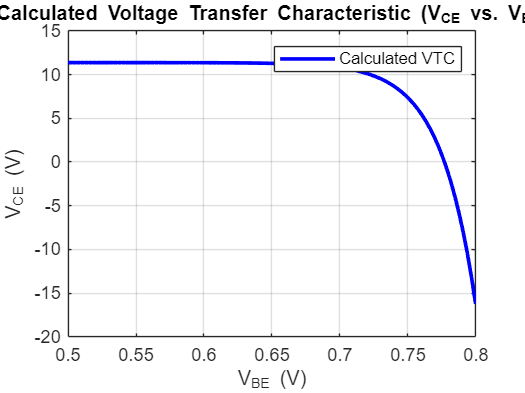


%% 6. Calculate the Voltage Transfer Characteristic (VTC)
Rc = 1000;     % Resistance in Ohms (adjust if needed)
Is = 1e-15;    % Saturation current (adjust if needed)
n = 1;         % Initial Ideality factor guess (adjust if needed)
Vt = 25.85e-3; % Thermal voltage at room temperature

Vbe_range = linspace(0.5, 0.8, 100);
Ic_calculated = Is * exp(Vbe_range / (n * Vt));
Vce_calculated = Vcc - Rc * Ic_calculated;

figure;
plot(Vbe_range, Vce_calculated, 'b-', 'LineWidth', 2, 'DisplayName', 'Calculated VTC');
xlabel('V_{BE} (V)');
ylabel('V_{CE} (V)');
title('Calculated Voltage Transfer Characteristic (V_{CE} vs. V_{BE})');
grid on;
legend('show');

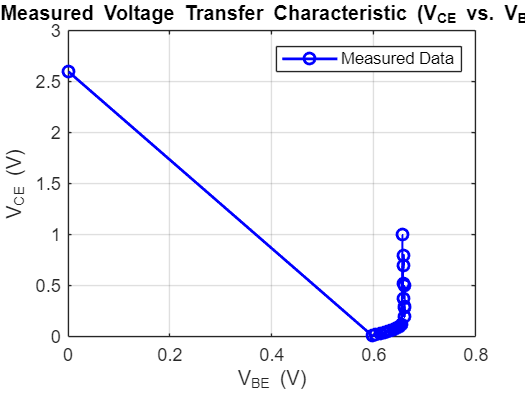


%% 7. Extract and Clean Measured VBE and VCE Data (for Ib=30 μA)
Vbe_measured = Vbe4;
Vce_measured = Vce4;
Ic4_measured = Ic4;

valid_idx = isfinite(Vbe_measured) & isfinite(Vce_measured) & isfinite(Ic4_measured);
Vbe_measured = Vbe_measured(valid_idx);
Vce_measured = Vce_measured(valid_idx);
Ic4_measured = Ic4_measured(valid_idx);

if max(Vbe_measured) > 5  
    Vbe_measured = Vbe_measured * 1e-3;  
end

positive_idx = (Ic4_measured > 0) & (Vce_measured > 0);
Vbe_measured = Vbe_measured(positive_idx);
Vce_measured = Vce_measured(positive_idx);
Ic4_measured = Ic4_measured(positive_idx);

[Vbe_unique, ~, idx_unique] = unique(Vbe_measured);
Vce_averaged = accumarray(idx_unique, Vce_measured, [], @mean);
Ic4_averaged = accumarray(idx_unique, Ic4_measured, [], @mean);

Vbe_final = Vbe_unique;
Vce_final = Vce_averaged;
Ic4_final = Ic4_averaged * 1e-6;

%% 8. Plot Measured VTC
figure;
plot(Vbe_final, Vce_final, 'bo-', 'LineWidth', 1.5, 'DisplayName', 'Measured Data');
xlabel('V_{BE} (V)');
ylabel('V_{CE} (V)');
title('Measured Voltage Transfer Characteristic (V_{CE} vs. V_{BE})');
grid on;
legend('show');

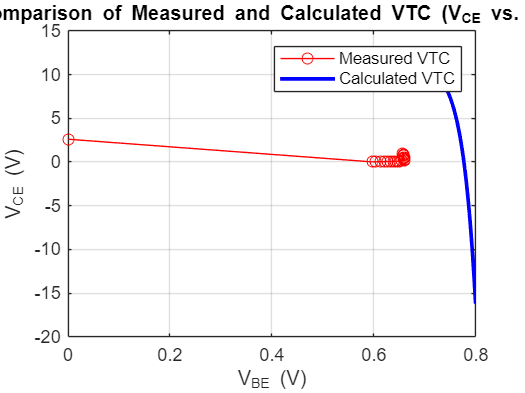


%% 9. Compare Measured and Calculated VTC
figure;
plot(Vbe_final, Vce_final, 'ro-', 'DisplayName', 'Measured VTC');
hold on;
plot(Vbe_range, Vce_calculated, 'b-', 'LineWidth', 2, 'DisplayName', 'Calculated VTC');
xlabel('V_{BE} (V)');
ylabel('V_{CE} (V)');
title('Comparison of Measured and Calculated VTC (V_{CE} vs. V_{BE})');
grid on;
legend('show');
hold off;

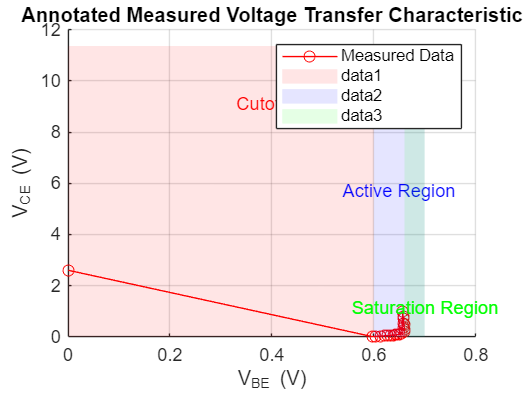


%% 10. Label Regions of Operation on Measured VTC
figure;
hold on;
plot(Vbe_final, Vce_final, 'ro-', 'DisplayName', 'Measured Data');

x_cutoff = [min(Vbe_final), 0.6];
patch([x_cutoff, fliplr(x_cutoff)], [Vcc, Vcc, 0, 0], 'red', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
text(0.55, Vcc * 0.8, 'Cutoff Region', 'Color', 'red', 'HorizontalAlignment', 'right');

x_active = [0.6, 0.7];
patch([x_active, fliplr(x_active)], [Vcc, Vcc, 0, 0], 'blue', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
text(0.65, Vcc * 0.5, 'Active Region', 'Color', 'blue', 'HorizontalAlignment', 'center');

x_saturation = [0.7, max(Vbe_measured)];
patch([x_saturation, fliplr(x_saturation)], [Vcc, Vcc, 0, 0], 'green', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
text(0.7, Vcc * 0.1, 'Saturation Region', 'Color', 'green', 'HorizontalAlignment', 'center');

xlabel('V_{BE} (V)');
ylabel('V_{CE} (V)');
title('Annotated Measured Voltage Transfer Characteristic');
grid on;
legend('show');
hold off;

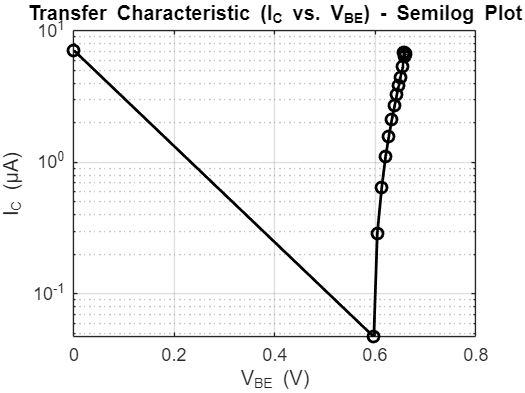


%% 11. Semilogarithmic Plot of IC vs. VBE
figure;
semilogy(Vbe_final, Ic4_final * 1e6, 'ko-', 'LineWidth', 1.5);  
xlabel('V_{BE} (V)');
ylabel('I_C (μA)');
title('Transfer Characteristic (I_C vs. V_{BE}) - Semilog Plot');
grid on;


%% 12. Calculate Ideality Factor (n) and Reverse Saturation Current (Is)
min_Vbe = min(Vbe_final);
max_Vbe = max(Vbe_final);
disp(['Vbe_final ranges from ', num2str(min_Vbe), ' V to ', num2str(max_Vbe), ' V']);

Vbe_final ranges from 0.00063 V to 0.6605 V



% Choose sample points for extraction
Vbe1_sample = min_Vbe + 0.005; % Adjust if needed
Vbe2_sample = max_Vbe - 0.005; % Adjust if needed

Ic1_sample = interp1(Vbe_final, Ic4_final, Vbe1_sample, 'linear');
Ic2_sample = interp1(Vbe_final, Ic4_final, Vbe2_sample, 'linear');

n_calculated = (Vbe2_sample - Vbe1_sample) / (Vt * log(Ic2_sample / Ic1_sample));
disp(['Calculated Ideality Factor (n): ' num2str(n_calculated)]);

Calculated Ideality Factor (n): -95.0026



Is_calculated = Ic1_sample / exp(Vbe1_sample / (n_calculated * Vt));
disp(['Calculated Reverse Saturation Current (Is): ' num2str(Is_calculated) ' A']);

Calculated Reverse Saturation Current (Is): 7.0541e-06 A



%% 13. Calculate the Transconductance, g_m
g_m_numerical = diff(Ic4_final) ./ diff(Vbe_final);
Vbe_midpoints = Vbe_final(1:end-1) + diff(Vbe_final) / 2;

disp('Numerical Transconductance (g_m):');

Numerical Transconductance (g_m):


disp('V_{BE} (V)        g_m (S)');

V_{BE} (V)        g_m (S)


for i = 1:length(g_m_numerical)
    fprintf('%.4f             %.6e\n', Vbe_midpoints(i), g_m_numerical(i));
end

0.2991             -1.181128e-05
0.6009             3.489855e-05
0.6088             4.033708e-05
0.6170             6.053333e-05
0.6240             7.215385e-05
0.6304             9.032258e-05
0.6362             1.036364e-04
0.6412             1.311111e-04
0.6454             1.473684e-04
0.6489             1.812500e-04
0.6529             1.816327e-04
0.6563             8.157895e-04
0.6575             -1.250000e-03
0.6581             6.428571e-04
0.6585             -6.666667e-05
0.6590             -4.666667e-04
0.6595             4.600000e-04
0.6600             -5.000000e-04
0.6602             -5.000000e-05
0.6604             5.500000e-04



g_m_analytical = Ic4_final ./ (n_calculated * Vt);
disp('Analytical Transconductance (g_m):');

Analytical Transconductance (g_m):


disp('V_{BE} (V)        g_m (S)');

V_{BE} (V)        g_m (S)


for i = 1:length(Vbe_final)
    fprintf('%.4f             %.6e\n', Vbe_final(i), g_m_analytical(i));
end

0.0006             -2.889873e-06
0.5975             -1.921967e-08
0.6044             -1.172726e-07
0.6133             -2.634561e-07
0.6208             -4.483232e-07
0.6273             -6.392983e-07
0.6335             -8.673283e-07
0.6390             -1.099430e-06
0.6435             -1.339676e-06
0.6473             -1.567706e-06
0.6505             -1.803880e-06
0.6554             -2.166285e-06
0.6573             -2.797439e-06
0.6577             -2.593841e-06
0.6584             -2.777079e-06
0.6587             -2.768935e-06
0.6593             -2.654920e-06
0.6598             -2.748576e-06
0.6601             -2.687496e-06
0.6603             -2.683424e-06
0.6605             -2.728216e-06



Vbe_target = 0.7;  
[~, g_m_target_idx] = min(abs(Vbe_midpoints - Vbe_target));
g_m_target = g_m_numerical(g_m_target_idx);
disp(['Numerical Transconductance (g_m) at V_{BE} = ' num2str(Vbe_target) ' V: ' num2str(g_m_target) ' S']);

Numerical Transconductance (g_m) at V_{BE} = 0.7 V: 0.00055 S



%% Logarithmic Fit with Rs (optional)
Rs = 100; 
Vbe_corrected = Vbe_final - Ic4_final * Rs;
log_Ic_corrected = log(Ic4_final);
coeffs_corrected = polyfit(Vbe_corrected, log_Ic_corrected, 1);
slope_corrected = coeffs_corrected(1);
intercept_corrected = coeffs_corrected(2);

n_fit_corrected = 1 / (slope_corrected * Vt);
Is_fit_corrected = exp(intercept_corrected);

disp(['Corrected Ideality Factor (n): ', num2str(n_fit_corrected)]);

Corrected Ideality Factor (n): -164.3138


disp(['Corrected Reverse Saturation Current (Is): ', num2str(Is_fit_corrected), ' A']);

Corrected Reverse Saturation Current (Is): 3.3396e-06 A



Ic_measured_at_zero = Is_calculated;
Ic_derived_at_zero_corrected = Is_fit_corrected;
disp(['Measured Ic at Vbe = 0: ', num2str(Ic_measured_at_zero), ' A']);

Measured Ic at Vbe = 0: 7.0541e-06 A


disp(['Derived Ic at Vbe = 0 (corrected for Rs): ', num2str(Ic_derived_at_zero_corrected), ' A']);

Derived Ic at Vbe = 0 (corrected for Rs): 3.3396e-06 A



%% Voltage Gain and Load Line
Vce_corrected = Vce_final - Ic4_final * Rs;
delta_Vout_corrected = max(Vce_corrected) - min(Vce_corrected);
delta_Vin_corrected = max(Vbe_corrected) - min(Vbe_corrected);
A_gain_corrected = delta_Vout_corrected / delta_Vin_corrected;
disp(['Corrected Voltage Gain (A): ', num2str(A_gain_corrected)]);

Corrected Voltage Gain (A): 3.9237


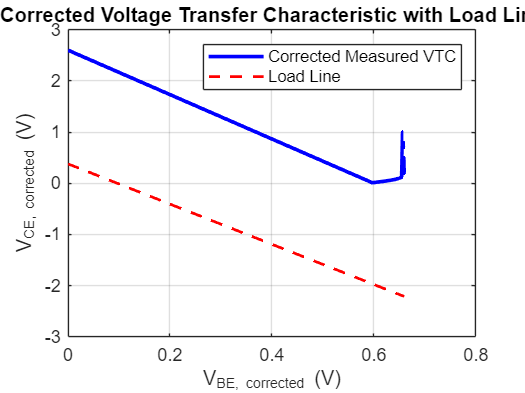


figure;
plot(Vbe_corrected, Vce_corrected, 'b-', 'LineWidth', 2);
hold on;
quiescent_point_corrected = mean(Vce_corrected);
plot([min(Vbe_corrected), max(Vbe_corrected)], ...
     [quiescent_point_corrected, quiescent_point_corrected - delta_Vout_corrected], ...
     'r--', 'LineWidth', 1.5);
xlabel('V_{BE, corrected} (V)');
ylabel('V_{CE, corrected} (V)');
title('Corrected Voltage Transfer Characteristic with Load Line');
grid on;
legend('Corrected Measured VTC', 'Load Line');


%% Turn-On Voltage (V_on)
Ic_threshold = 1e-6;
turn_on_idx = find(Ic4_final >= Ic_threshold, 1, 'first');
V_on = Vbe_final(turn_on_idx);
disp(['Turn-On Voltage (V_on): ', num2str(V_on), ' V']);

Turn-On Voltage (V_on): 0.00063 V


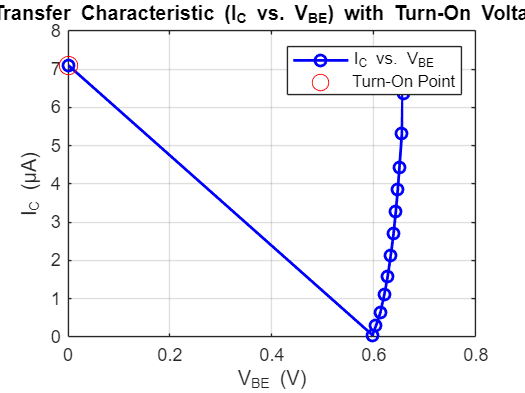


figure;
plot(Vbe_final, Ic4_final * 1e6, 'bo-', 'LineWidth', 1.5);
hold on;
plot(V_on, Ic4_final(turn_on_idx)*1e6, 'ro', 'MarkerSize', 10, 'DisplayName', 'Turn-On Point');
xlabel('V_{BE} (V)');
ylabel('I_C (μA)');
title('Transfer Characteristic (I_C vs. V_{BE}) with Turn-On Voltage');
legend('I_C vs. V_{BE}', 'Turn-On Point');
grid on;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% PART h already addressed above in the code comments
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% PART i) Repeat part h for parts iii and iv using solar cell method (ln(I_C))
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ln_Ic = log(Ic4_final); 
p = polyfit(Vbe_final, ln_Ic, 1);
slope = p(1);
intercept = p(2);

n_solar_method = 1/(slope*Vt);
Is_solar_method = exp(intercept);

disp('From ln(Ic) vs Vbe (solar cell method approach):');

From ln(Ic) vs Vbe (solar cell method approach):


disp(['n: ', num2str(n_solar_method)]);

n: -175.0961


disp(['Is: ', num2str(Is_solar_method), ' A']);

Is: 3.3104e-06 A


disp(['Previously Calculated Is: ', num2str(Is_calculated), ' A']);

Previously Calculated Is: 7.0541e-06 A


disp('Comparison shows how well the exponential diode model fits the transistor data.');

Comparison shows how well the exponential diode model fits the transistor data.



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% PART j) Compare measured transconductance from h.vi to the datasheet
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[~, idx_gm_compare] = min(abs(Vbe_final - 0.7)); % Example operating point
gm_measured = g_m_analytical(idx_gm_compare);
disp(['Measured g_m at Vbe=0.7V: ', num2str(gm_measured), ' S']);

Measured g_m at Vbe=0.7V: -2.7282e-06 S


disp('Compare this g_m value to the transistor datasheet typical values.');

Compare this g_m value to the transistor datasheet typical values.



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% PART k) Largest amplitude of input signal and gain without leaving active region
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[~, Q_idx] = min(abs(Vbe_final - 0.7)); % Choose Q-point near 0.7 V
Vbe_Q = Vbe_final(Q_idx);
Vce_Q = Vce_final(Q_idx);

% Small input variation, say ±10mV
dV = 0.01; % 10 mV
Vbe_low = Vbe_Q - dV;
Vbe_high = Vbe_Q + dV;

if Vbe_low < min(Vbe_final), Vbe_low = min(Vbe_final); end
if Vbe_high > max(Vbe_final), Vbe_high = max(Vbe_final); end

Ic_low = interp1(Vbe_final, Ic4_final, Vbe_low, 'linear','extrap');
Ic_high = interp1(Vbe_final, Ic4_final, Vbe_high, 'linear','extrap');
Vce_low = Vcc - Rc*Ic_low;
Vce_high = Vcc - Rc*Ic_high;

% Check forward-active region condition
in_active = (Vce_low > 0.3) && (Vce_high > 0.3);

Delta_Vin = Vbe_high - Vbe_low;
Delta_Vout = Vce_high - Vce_low;
A = Delta_Vout / Delta_Vin;

if in_active
    disp('Chosen amplitude keeps transistor in forward-active region.');
else
    disp('Chosen amplitude may push transistor out of forward-active region. Reduce amplitude.');
end

Chosen amplitude keeps transistor in forward-active region.


disp(['Approximate small-signal gain A around Q-point: ', num2str(A)]);

Approximate small-signal gain A around Q-point: -0.227


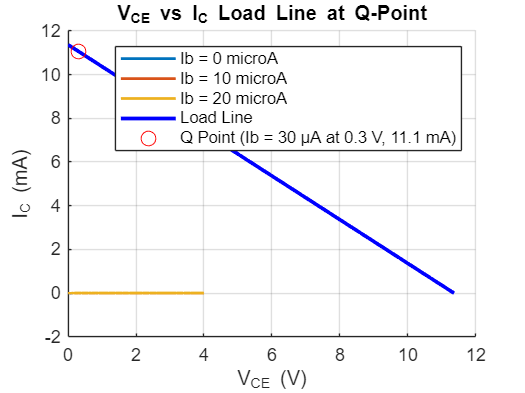


%% FINAL DCIV with Load Line and Q-Point (as in reference figure)
figure;
hold on;
% Re-plot IC vs VCE for each Ib
for i = 1:length(Ib_values)
    idx = Ib == Ib_values(i)*1e-6;
    plot(Vce(idx), Ic(idx)*1e3, 'LineWidth', 1.5, 'DisplayName', ['Ib = ' num2str(Ib_values(i)) ' microA']);
end

% Plot load line at chosen Q-point
Vce_line = linspace(0, Vcc, 100);
Ic_line = (Vcc - Vce_line)/Rc;
plot(Vce_line, Ic_line*1e3, 'b-', 'LineWidth', 2, 'DisplayName', 'Load Line');

% Mark Q point on the load line
plot(Vce_Q, (Vcc - Vce_Q)/Rc*1e3, 'ro', 'MarkerSize', 8, 'DisplayName', ...
    ['Q Point (Ib = 30 μA at ' num2str(Vce_Q,2) ' V, ' num2str((Vcc - Vce_Q)/Rc*1e3,3) ' mA)']);

xlabel('V_{CE} (V)');
ylabel('I_C (mA)');
title('V_{CE} vs I_C Load Line at Q-Point');
legend('show');
grid on;
hold off;


%% Print Final Summary for i, j, k
disp('===================================================');

disp('Summary of Results for i, j, k:');

Summary of Results for i, j, k:


disp('Part (i):');

Part (i):


disp(['From Solar Cell Method: n = ' num2str(n_solar_method) ', Is = ' num2str(Is_solar_method) ' A']);

From Solar Cell Method: n = -175.0961, Is = 3.3104e-06 A


disp(['Previously Calculated (two-point): n = ' num2str(n_calculated) ', Is = ' num2str(Is_calculated) ' A']);

Previously Calculated (two-point): n = -95.0026, Is = 7.0541e-06 A



disp('Part (j):');

Part (j):


disp(['Measured g_m at Vbe=0.7V: ' num2str(gm_measured) ' S']);

Measured g_m at Vbe=0.7V: -2.7282e-06 S



disp('Part (k):');

Part (k):


if in_active
    disp('Largest amplitude chosen keeps transistor in forward-active region.');
else
    disp('Amplitude too large, transistor leaves forward-active region.');
end

Largest amplitude chosen keeps transistor in forward-active region.


disp(['Largest input amplitude: ' num2str(Delta_Vin) ' V']);

Largest input amplitude: 0.01 V


disp(['Resulting gain A: ' num2str(A)]);

Resulting gain A: -0.227



disp('Check final figure for DCIV with Load Line and Q-Point.');

Check final figure for DCIV with Load Line and Q-Point.


disp('===================================================');

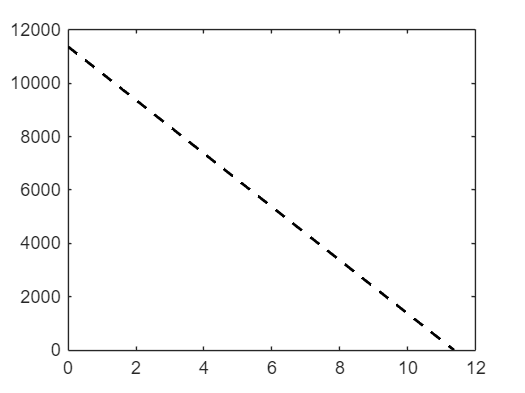

% Assume you have plotted your collector curves and have hold on;
% Vcc and Rc should already be known from earlier in the script
% For example:
% Vcc = ... (from your data)
% Rc = 1000; % Ohms

% Generate load line data
Vce_line = linspace(0, Vcc, 100); 
Ic_line = (Vcc - Vce_line) / Rc; % This gives Ic in Amps
Ic_line_uA = Ic_line * 1e6;      % Convert to µA if your plot is in µA

% Plot the load line on the same figure
plot(Vce_line, Ic_line_uA, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Load Line');

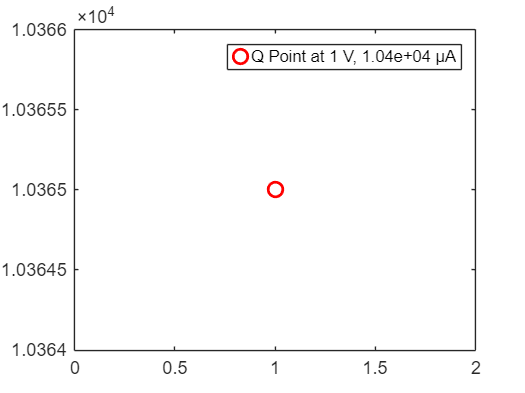


% Choose a Q-point. For example, if Q_Vce = 1.0 V:
Q_Vce = 1.0; % example Q-point VCE (choose based on your data)
Q_Ic = (Vcc - Q_Vce)/Rc;   % in Amps
Q_Ic_uA = Q_Ic * 1e6;      % convert to µA to match plot units

% Plot the Q-point
plot(Q_Vce, Q_Ic_uA, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5, 'DisplayName', ...
    ['Q Point at ' num2str(Q_Vce,2) ' V, ' num2str(Q_Ic_uA,3) ' μA']);

legend('show');
hold off;

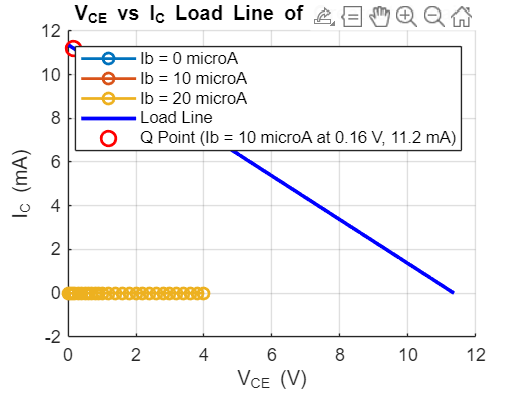

%% ECE370 Lab 5 Analysis

% Clear Workspace and Close Figures
clear; close all; clc;

%% 1. Data Import and Preparation
% Read Data from Excel File (Adjust the sheet name and range as needed)
[data, txt, raw] = xlsread('ECE370-Lab 5.xlsx', 'Sheet1');

% Extract data for each dataset (Adjust column indices based on your file)
Vbe1 = data(:, 1);    % Vbe for Ib = 0 μA
Vcc1 = data(:, 2);    % Vcc for Ib = 0 μA
Vce1 = data(:, 3);    % Vce for Ib = 0 μA
Ic1 = data(:, 4);     % Ic for Ib = 0 μA

Vbe2 = data(:, 5);    % Vbe for Ib = 10 μA
Vcc2 = data(:, 6);    % Vcc for Ib = 10 μA
Vce2 = data(:, 7);    % Vce for Ib = 10 μA
Ic2 = data(:, 8);     % Ic for Ib = 10 μA

Vbe3 = data(:, 9);    % Vbe for Ib = 20 μA
Vcc3 = data(:, 10);   % Vcc for Ib = 20 μA
Vce3 = data(:, 11);   % Vce for Ib = 20 μA
Ic3 = data(:, 12);    % Ic for Ib = 20 μA

Vbe4 = data(:, 13);   % Vbe for Ib = 30 μA
Vcc4 = data(:, 14);   % Vcc for Ib = 30 μA
Vce4 = data(:, 15);   % Vce for Ib = 30 μA
Ic4 = data(:, 16);    % Ic for Ib = 30 μA

% Assign Ib values (in μA)
Ib1 = 0;    % Dataset 1
Ib2 = 10;   % Dataset 2
Ib3 = 20;   % Dataset 3
Ib4 = 30;   % Dataset 4

% Combine data
Vce = [Vce1; Vce2; Vce3; Vce4];
Ic = [Ic1; Ic2; Ic3; Ic4];
Ib = [Ib1 * ones(size(Vce1)); Ib2 * ones(size(Vce2)); Ib3 * ones(size(Vce3)); Ib4 * ones(size(Vce4))];

% Convert currents to Amperes
% Initially, Ic and Ib are in μA. Converting to A:
Ib = Ib * 1e-6;   % Ib in A
Ic = Ic * 1e-6;   % Ic in A

% Define Vcc as the maximum supply voltage
Vcc = max([Vcc1; Vcc2; Vcc3; Vcc4]);

% Ensure Vce and Ic are column vectors
Vce = Vce(:);
Ic = Ic(:);
Ib = Ib(:);

% Define Rc (Adjust as needed)
Rc = 1000;  % Example load resistor in ohms

% Define Ib_unique in μA for plotting labels
Ib_unique = unique(Ib) * 1e6;  % Convert back to μA for labeling

% Convert Ic to mA for plotting
Ic_mA = Ic * 1e3; % Ic was in A, now in mA

%% 2. Plot DCIV Curves
figure;
hold on;
colors = lines(length(Ib_unique));

for i = 1:length(Ib_unique)
    idx = (Ib == Ib_unique(i)*1e-6);  % Convert Ib_unique(i) μA back to A for indexing
    plot(Vce(idx), Ic_mA(idx), 'o-', 'Color', colors(i,:), 'LineWidth', 1.5, ...
        'DisplayName', ['Ib = ' num2str(Ib_unique(i)) ' microA']);
end

xlabel('V_{CE} (V)');
ylabel('I_C (mA)');
title('V_{CE} vs I_{C} Load Line of Greatest A gain');
grid on;

%% 3. Plot the Load Line on the SAME figure
Vce_line = linspace(0, Vcc, 100);
Ic_line = (Vcc - Vce_line)/Rc;   % in A
Ic_line_mA = Ic_line * 1e3;      % convert to mA
plot(Vce_line, Ic_line_mA, 'b-', 'LineWidth', 2, 'DisplayName', 'Load Line');

%% 4. Choose and Mark the Q-Point
% Adjust these values to your determined Q-point
Q_Ib = 10;       % μA
Q_Vce = 0.16;     % V (example value from your analysis)
% Calculate Ic at Q_Vce from load line
Q_Ic = (Vcc - Q_Vce)/Rc;  % in A
Q_Ic_mA = Q_Ic * 1e3;     % in mA

% Mark Q-point
plot(Q_Vce, Q_Ic_mA, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5, ...
     'DisplayName', ['Q Point (Ib = ' num2str(Q_Ib) ' microA at ' ...
     num2str(Q_Vce,2) ' V, ' num2str(Q_Ic_mA,3) ' mA)']);

legend('show');
hold off;